# Setup

% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;   
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

Heterophily

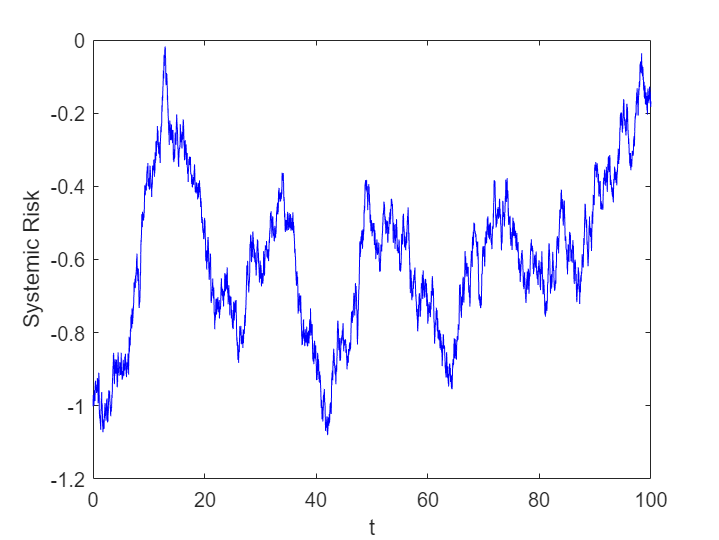

threshold = 1;
x = SolveSDE(t, N, h, sig, theta, @(t, x) heterophily(x, threshold));
PlotSDE(t, x);

Homophily

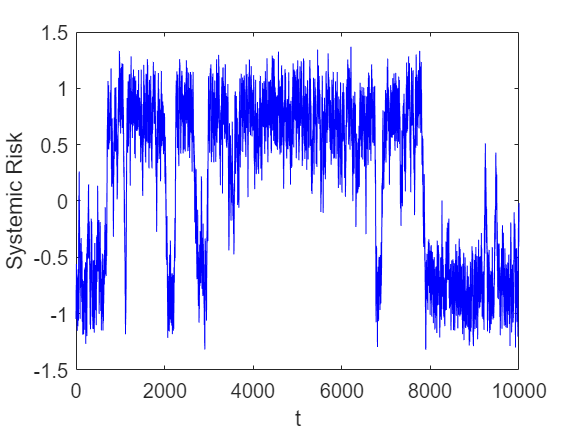

x = SolveSDE(t, N, h, sig, theta, @(t, x) homophily(x, threshold));
PlotSDE(t, x);

Disconnected/Bipartite

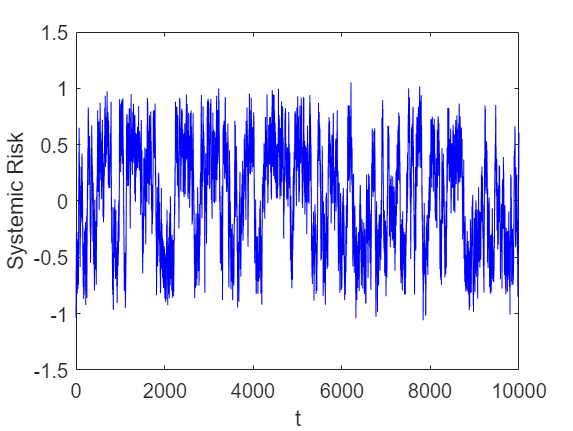

x = SolveSDE(t, N, h, sig, theta, @(t, x) bipartite(x));

PlotSDE(t, x);

Connected

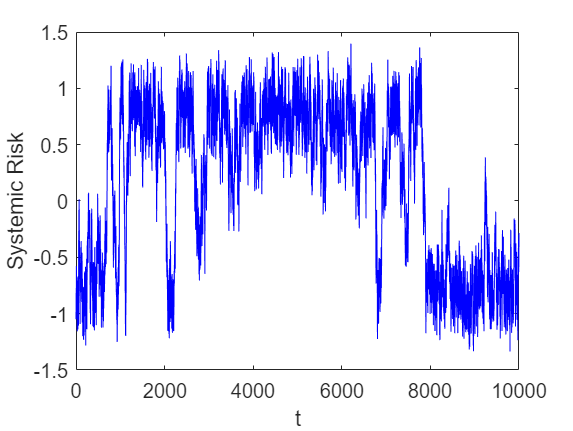

x = SolveSDE(t, N, h, sig, theta, @(t, x) connected(x));
PlotSDE(t, x);

Erdos-Renyi

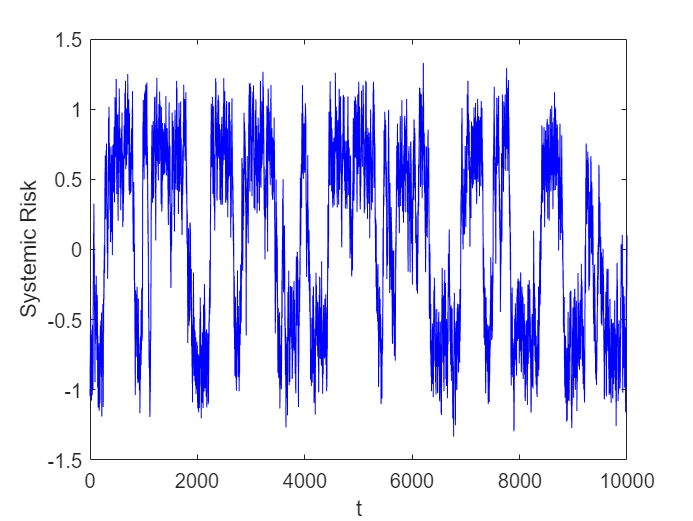

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.5));
PlotSDE(t, x);

Random graph (with p = 0.1)

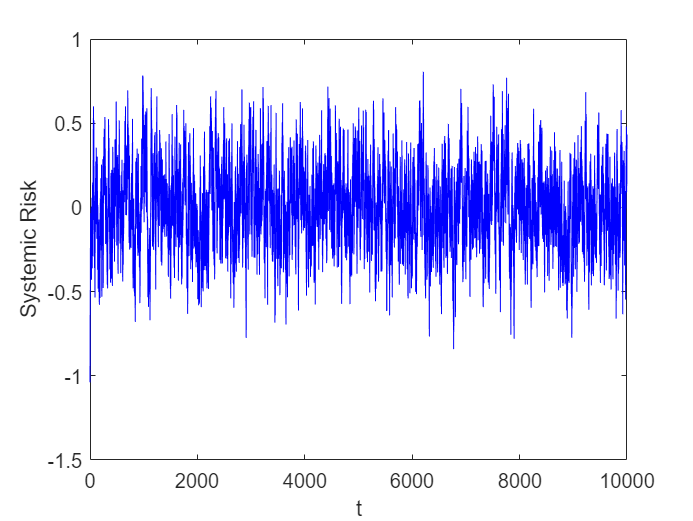

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.1));
PlotSDE(t, x);

Random graph (with p = 0.3)

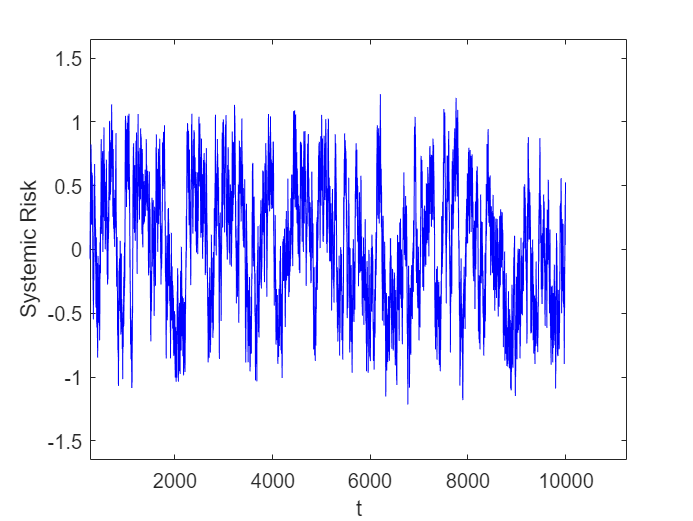

x = SolveSDE(t, N, h, sig, theta, @(t, x) ErdosRenyi(x, 0.3));
PlotSDE(t, x);

Markov Switching process

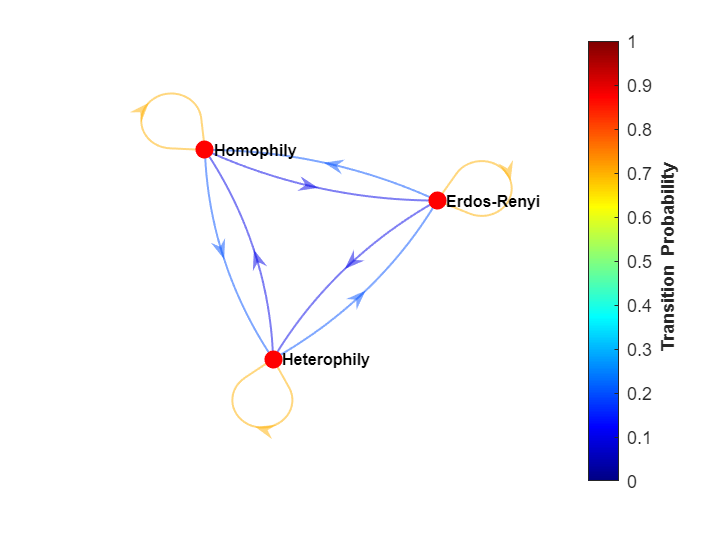

% Define a Markov structure with three fields:

% Field 1: Function Handles (redundant but left in for now)
value1 = {{@(x)homophily(x, 1), @(x)heterophily(x, 1), @(x)ErdosRenyi(x, 0.3)}};
% Field 2: Transition Matrix
P = [0.7, 0.2, 0.1;
     0.1, 0.7, 0.2;
     0.2, 0.1, 0.7];
% Field 3: Initial state
initial_state = 1;

MarkovStruct = struct(...
    'states', value1, ...
    'P', P, ...
    'state', initial_state ...
    );

% Return Markov simulations and markov process
[X, mc] = MarkovSwitching(MarkovStruct, t);

% Plot Markov chain and simulations
graphplot(mc, 'ColorEdges', true);

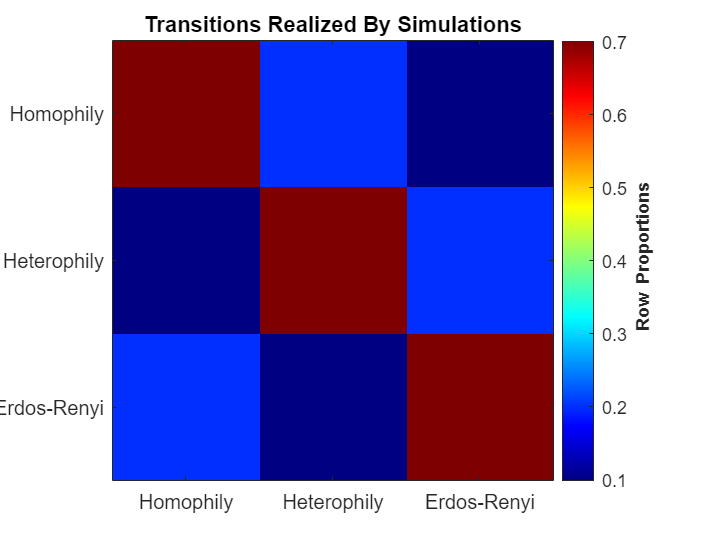

simplot(mc, X, 'Type', 'transitions');

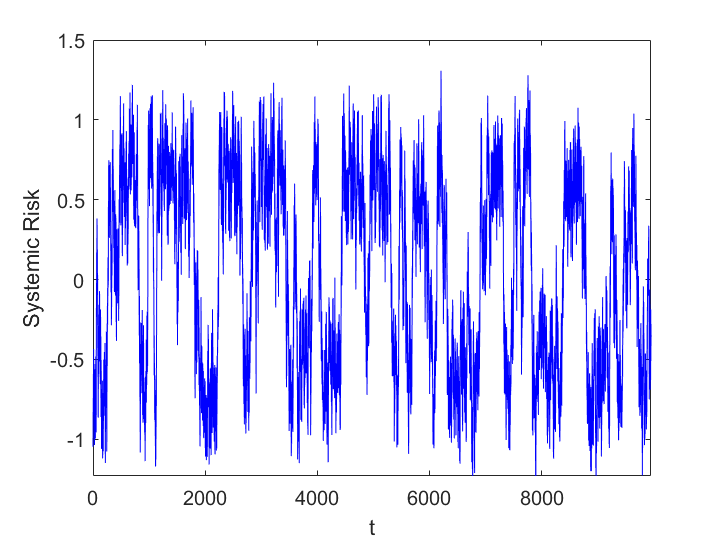


% Solve SDE and plot
x = SolveSDE(t, N, h, sig, theta, @(t, x) EvalMarkov(t, x, X));
PlotSDE(t, x);